# Reduced Order Modeling Workflow

In this exercise, we will walk through the process of creating a reduced order model using the example of a battery system.

## 1. Install the Reduced Order Modeling Support Package

(You can skip to the next section if you have already installed the support package)

You can install this by using the Add-on Manager => Reduced Order Modeling Support Package

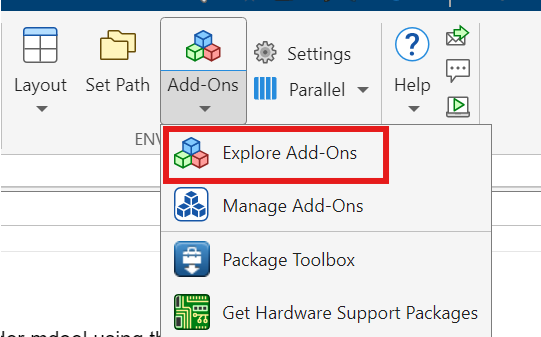

OR

You can download the support package from the [File Exchange](https://www.mathworks.com/matlabcentral/fileexchange/156364-reduced-order-modeling-support-package-beta)

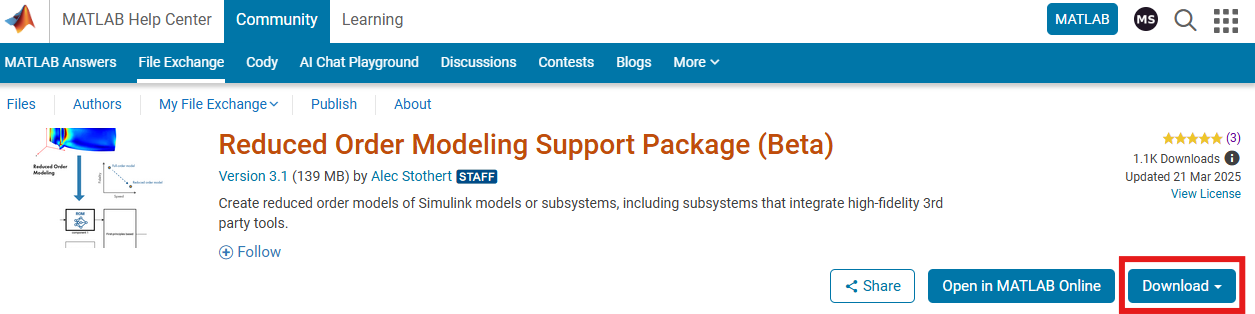

And install it using the following command [`matlab.addons.install`](https://www.mathworks.com/help/matlab/ref/matlab.addons.install.html)` as shown in the example code below.`

Example code:

## 2. Getting started with the Reduced Order Modeling Workflow

Once the support package is installed we can called the app using the [reducedOrderModeler](https://viewer.mathworks.com/?viewer=plain_code&url=https%3A%2F%2Fwww.mathworks.com%2Fmatlabcentral%2Fmlc-downloads%2Fdownloads%2F0cee96ac-b9e3-4632-9809-a7fd7d78d2b0%2F1742562087%2Ffiles%2FreducedOrderModeler.m&embed=web) command.

ex1Folders = genpath(pwd);
addpath(ex1Folders);

Load the model and the Reduced Order Modeler app

load_system('OriginalBatteryModel.slx');
open_system("OriginalBatteryModel.slx")
reducedOrderModeler;

This will provide options to create a reduced order model either from a Simulink Model or from data imported in MATLAB as seen below:

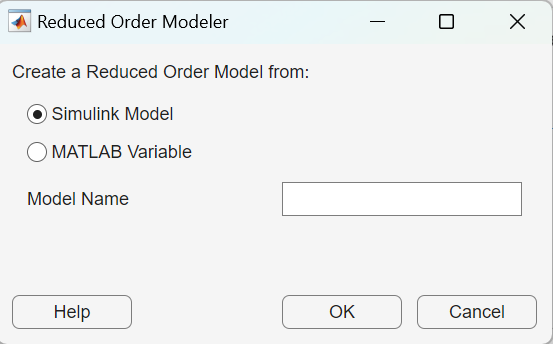

Type in the name of the Simulink model in the Model Name Dialog Box: **OriginalBatteryModel.**

This will load the model and the ROM Application.

We can walk through the battery model and understand the components in the model.

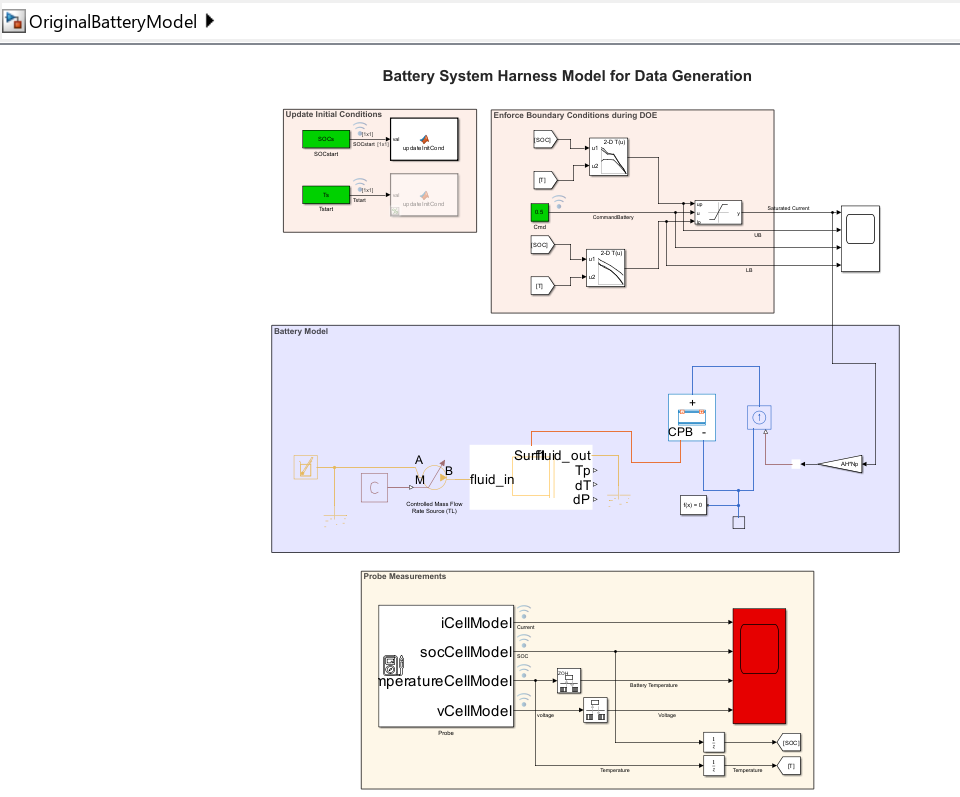

## 3. Select Inputs and Outputs for creating our ROM

Our goal is to create a reduced order model for a battery pack which can be used for embedded real-time model predictive control (MPC) and nonlinear state estimation applications.

In our reduced order model our inputs would be a given current profile from the battery at a given initial SOC and initial temperature, and outputs will be resultant battery temperature and battery voltage.

 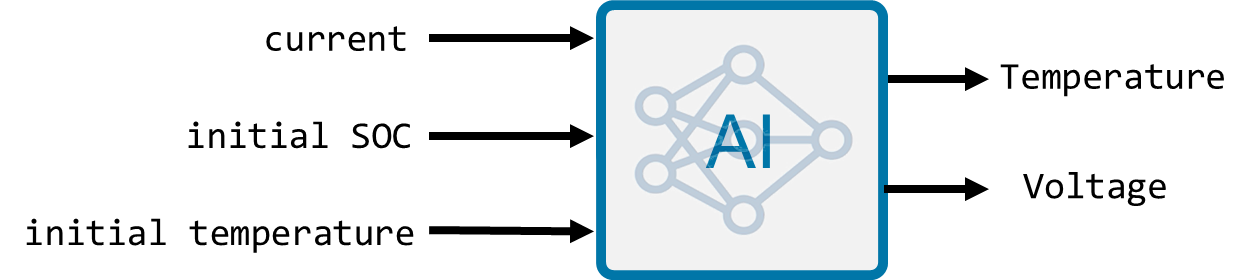

### 3.1 Setup the session in the Reduced Order Modeler app

- Now we will open the reduced order modeler app and create a new session

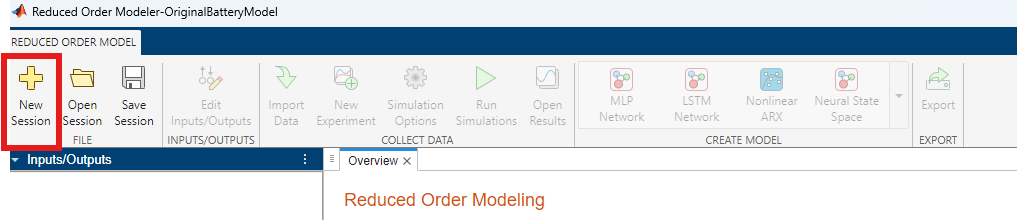

        2. Next, we click on "Select Signals" to select our inputs and outputs from our model to create the ROM

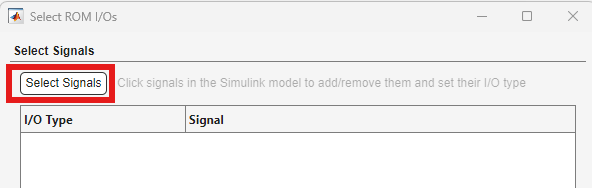

        3. Select the ROM Inputs and Outputs from the model (The green block represents the ROM input and red color ROM Output)

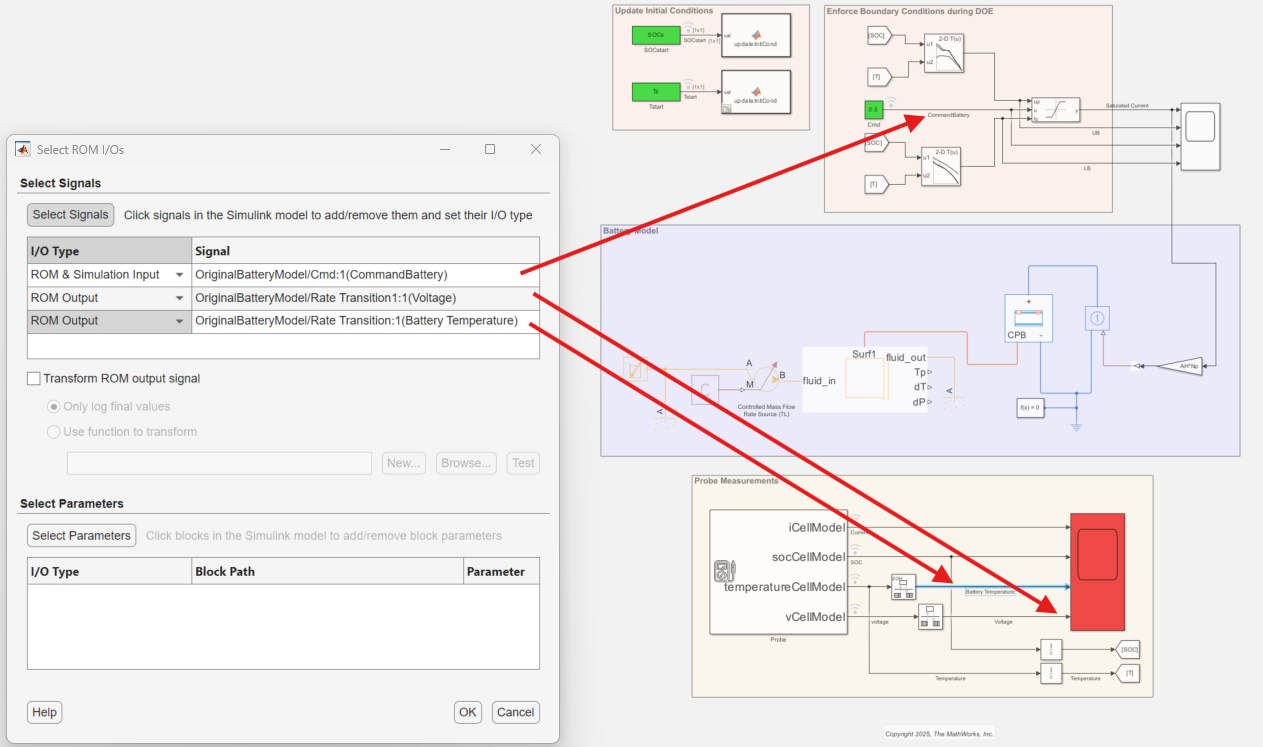

            4. Select the parameter for creating the ROM. In our case, it is the Initial SOC and the Initial Temperature

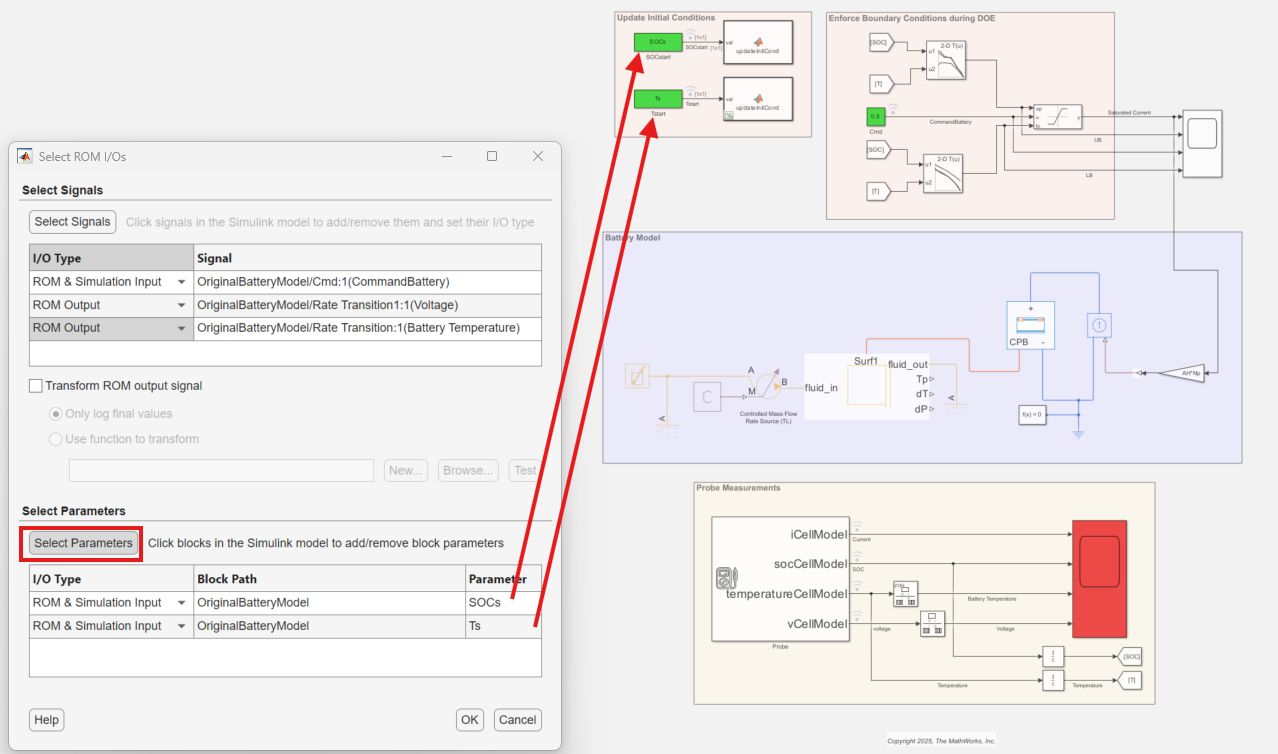

### 3.2 Create Design of Experiments to collect the data for ROM   

            5. Create a new experiement to vary the input signals and parameters to generate the data for creating our ROM

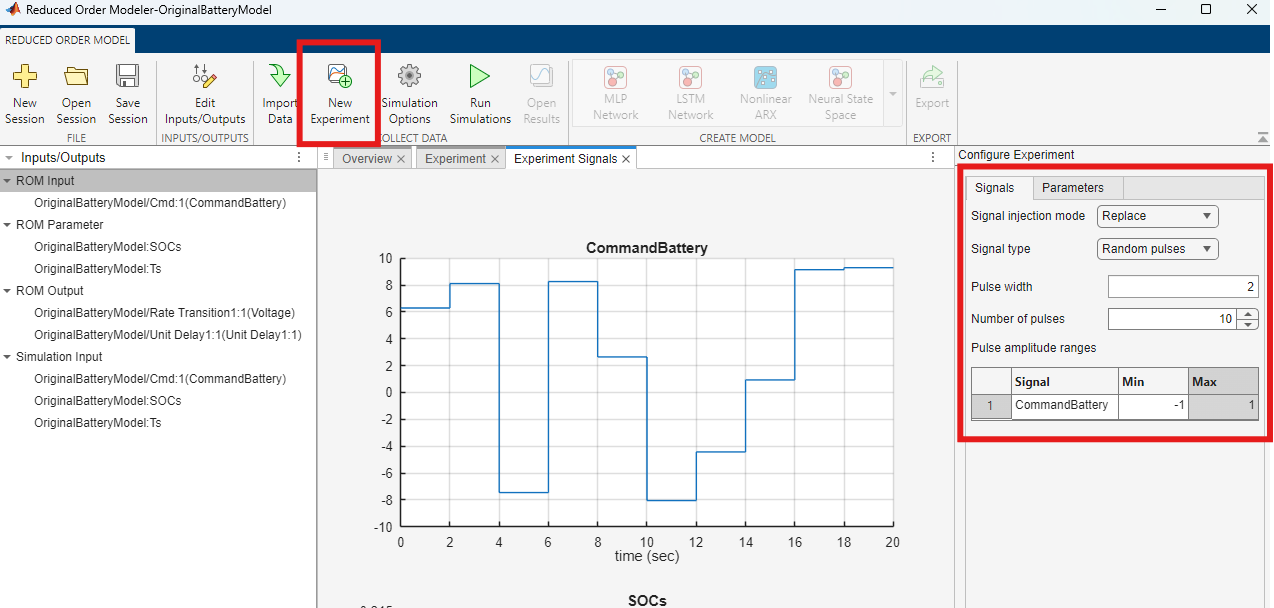

            6. Vary the initial parameters to generate data across different initial conditions

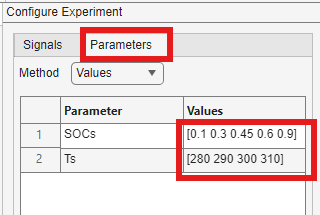

## 4. Configure settings for parallel and collect data by running the simulations

    1. Start the parallel pool on your workers by clicking on 'Start Parallel Pool' option located in bottom left of your MATLAB Window.  

    2. Attach the required files to the workers (this is required when running on MATLAB Online)

%pool = gcp;
%pool.addAttachedFiles("+moduleExample"); %% this is to provide battery module access to the parallel workers to simulate our model

    3. Back in the ROM App click on 'Simulation Options'  and select 'Use parallel when running multiple Simulations'

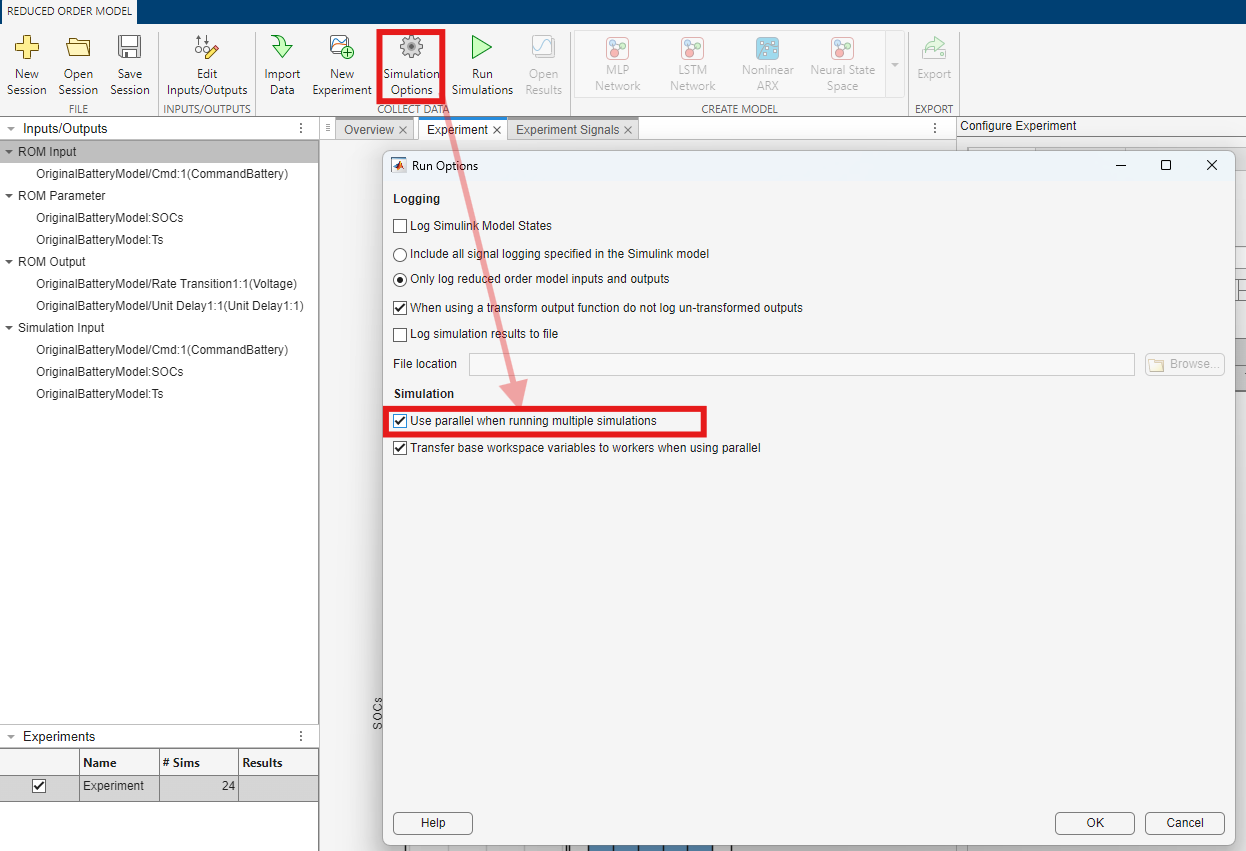

     4. Click on Run Simulations to start running the Simulink model and collecting data

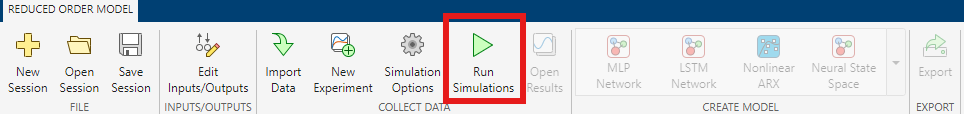

    5. Once completed you can visualize the simulation results

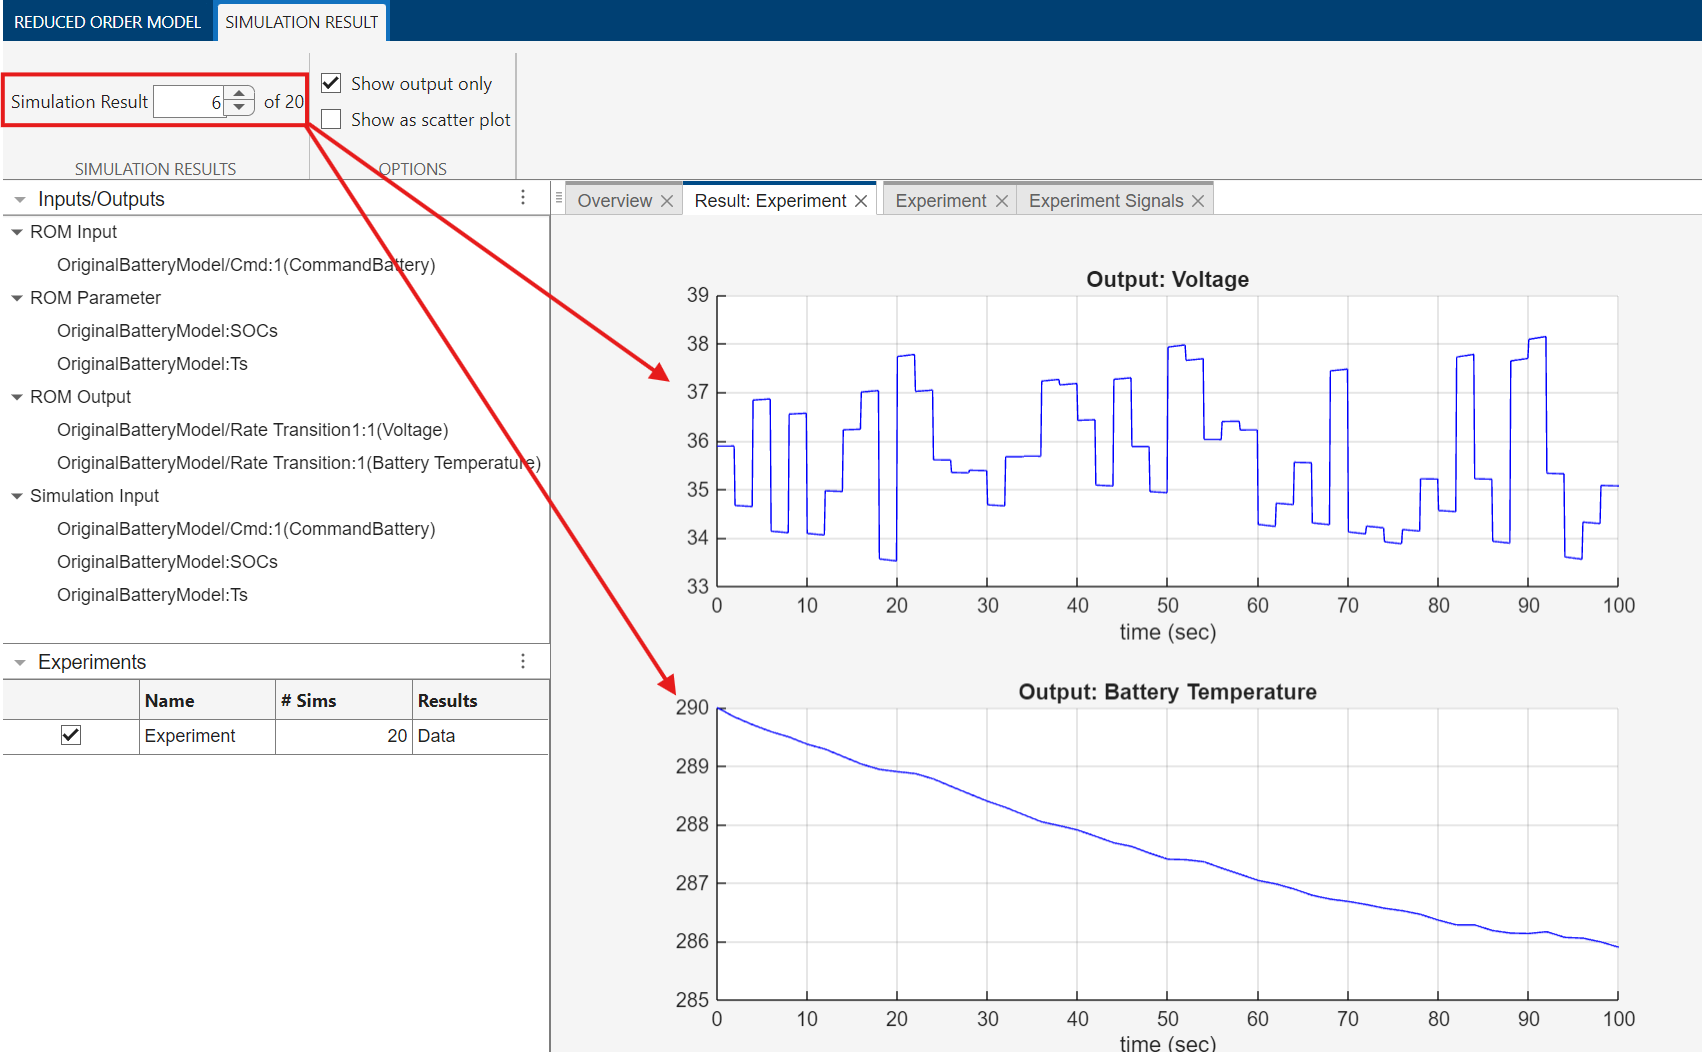

    6. To save time, instead of running more simulation, we will load simulation results from previous runs.

 **Click on "Open Session" >> Browse to "\01-ROM of a Battery System\Data\ROMAppSessionFiles" and select "OriginalBatteryModel_ExpResults"**

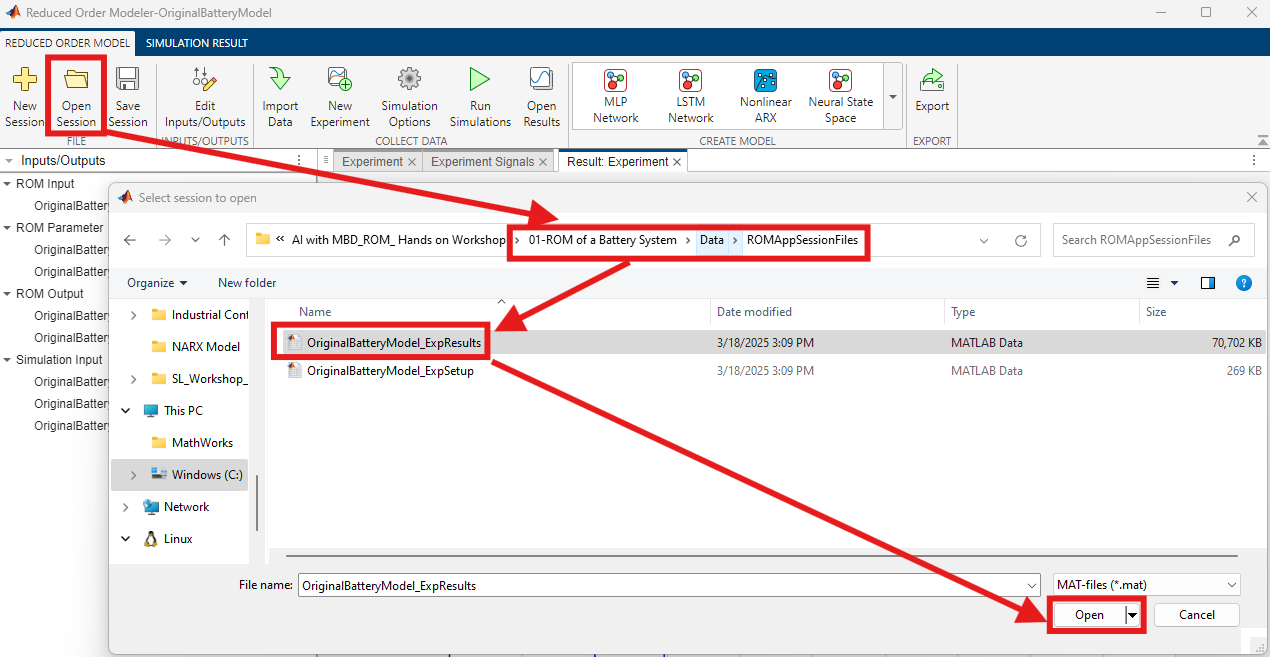

    7. The new file has 4 experiment setups with 20 runs each. View the various experimental settings and results.

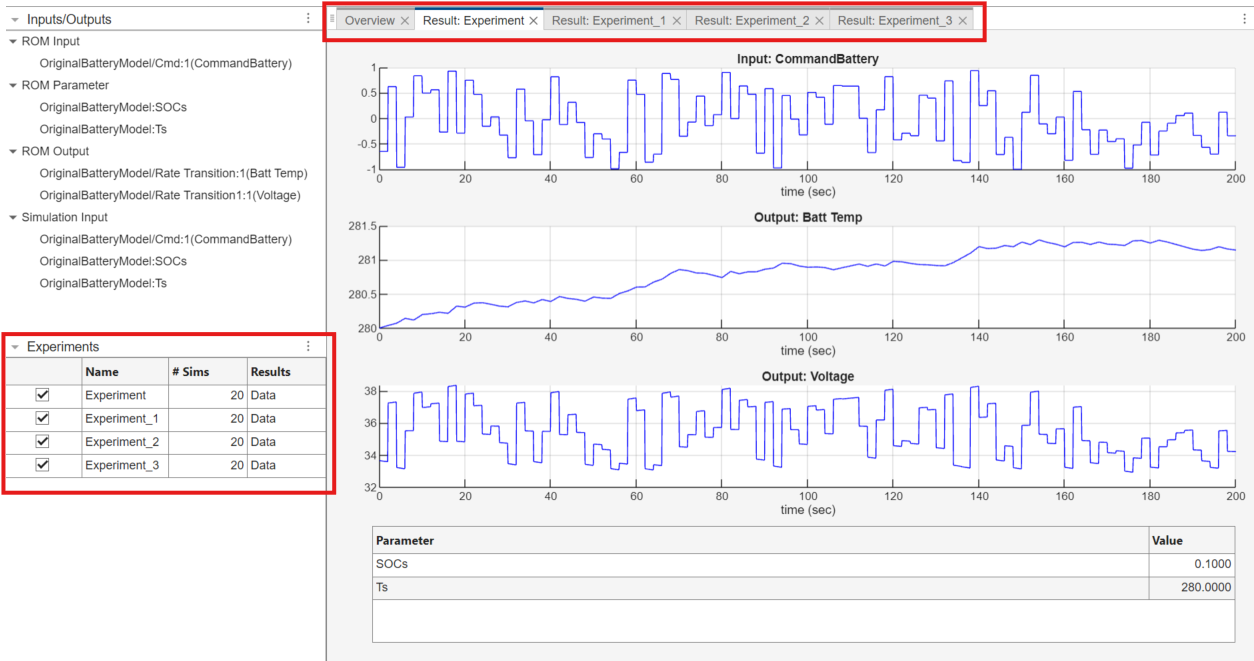

## 5. Creating and Training the Reduced Order Model

- Select one of the default available models to create a ROM. For this workshop, lets select Nonlinear ARX model.

            We will also briefly go through the other model types in the presentation

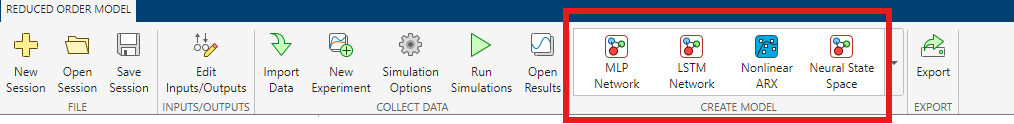

            2. Select all the experiments and click on OK

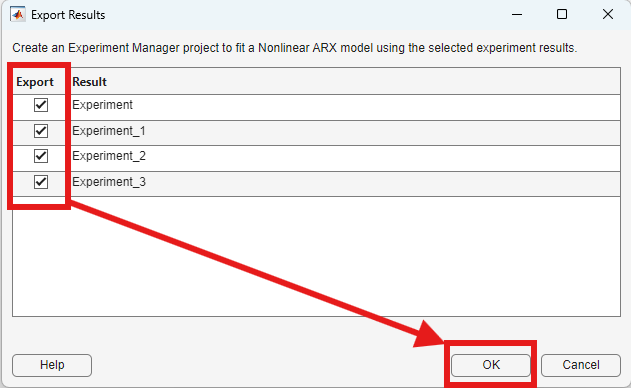

            3. The experiment manager will launch up. Click on "New Project" and save your project in the root folder naming "ExperimentProject". This will create a new project with default hyperparmeter settings. You can view and edit the training function using the Edit button.

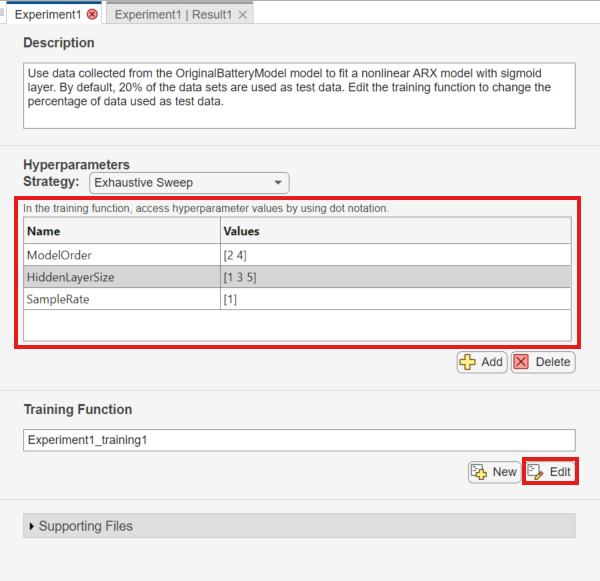

            4. You can setup the execution to "Simultaneous" to run the model training using parallel cores and then click on the Run button.

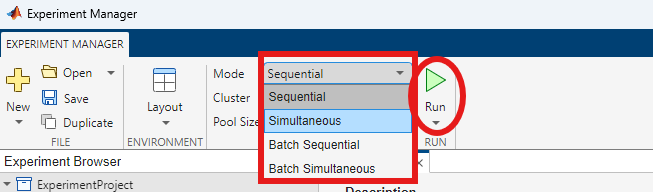

            5. View and compare the results in the experiment manager to select the best model or to perform more experimentation.

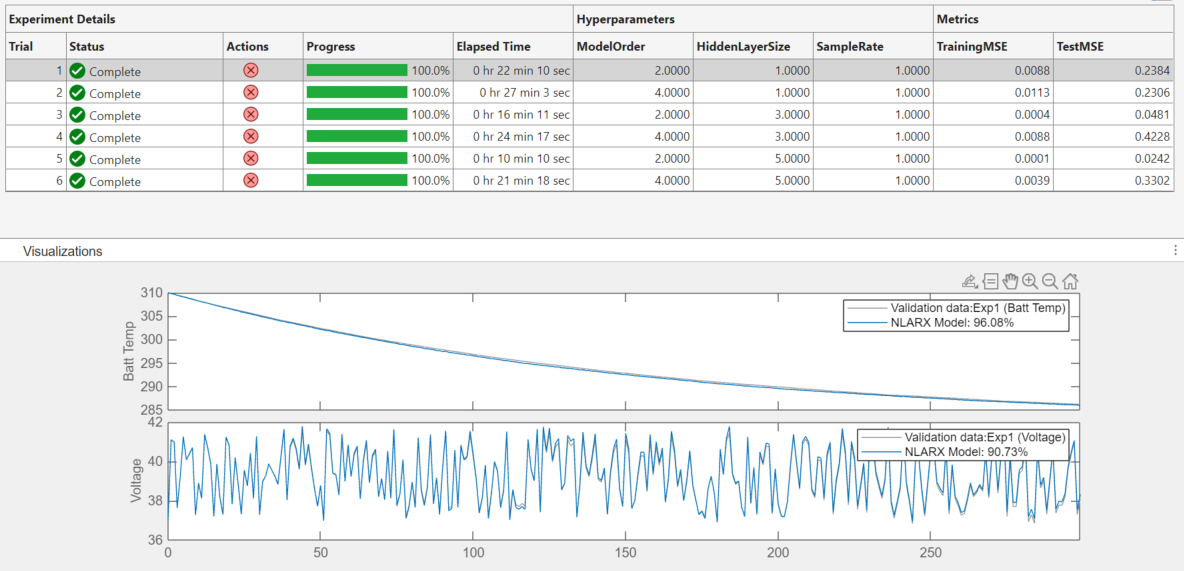

        6. Models with low **TestMSE** , comparable **TrainingMSE** , and **good fit to validation responses** are good potential models. To export a selected model to the MATLAB workspace, right-click the corresponding row. Given the randomness in the experiment design for collecting data and Nonlinear ARX initialization, exact model performance may vary.

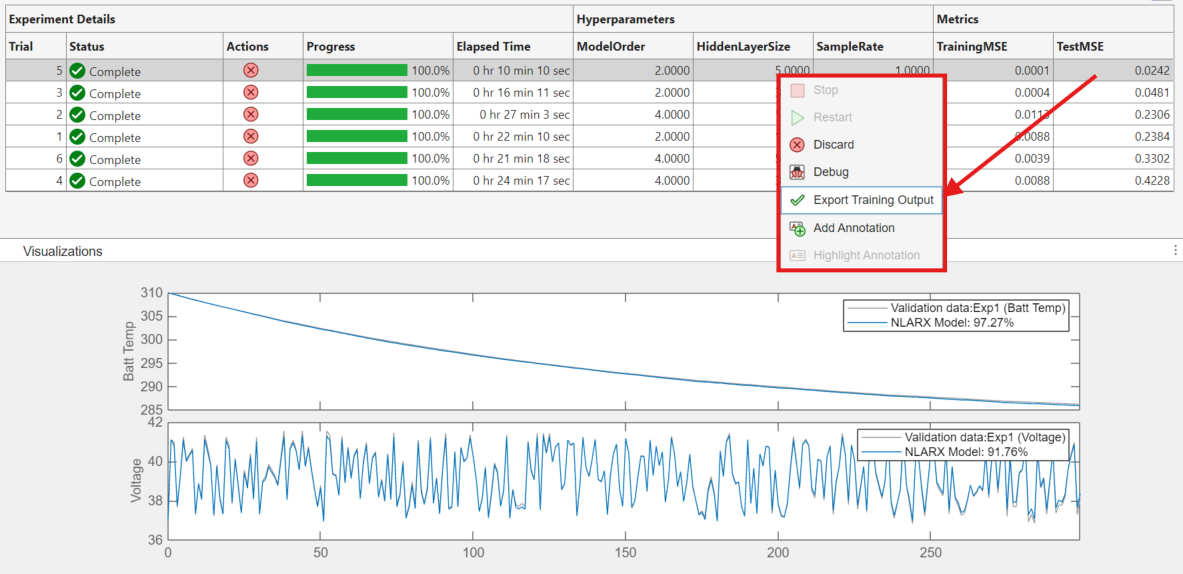

Export the model and provide a suitable name. we will be validating and testing this exported model.

## 6. Testing and Comparing the Reduced Order Models

- Once exported the model can then be used in Simulink to replace the high-fidelity model. You can check a comparison of the Nonlinear ARX model with the original Simscape Battery model from this example.

Load and open the Simulink model

load_system('ValidateROMBatteryModel.slx');
open_system("ValidateROMBatteryModel.slx")

2. Replace the existing Nonlinear ARX model with the model you have exported to test your model peformance.

- Double click on the Nonlinear ARX Model block located within the Nonlinear ARX Battery Model subsystem.

- Change the name of the model by replacing the current model with your exported model as shown below:

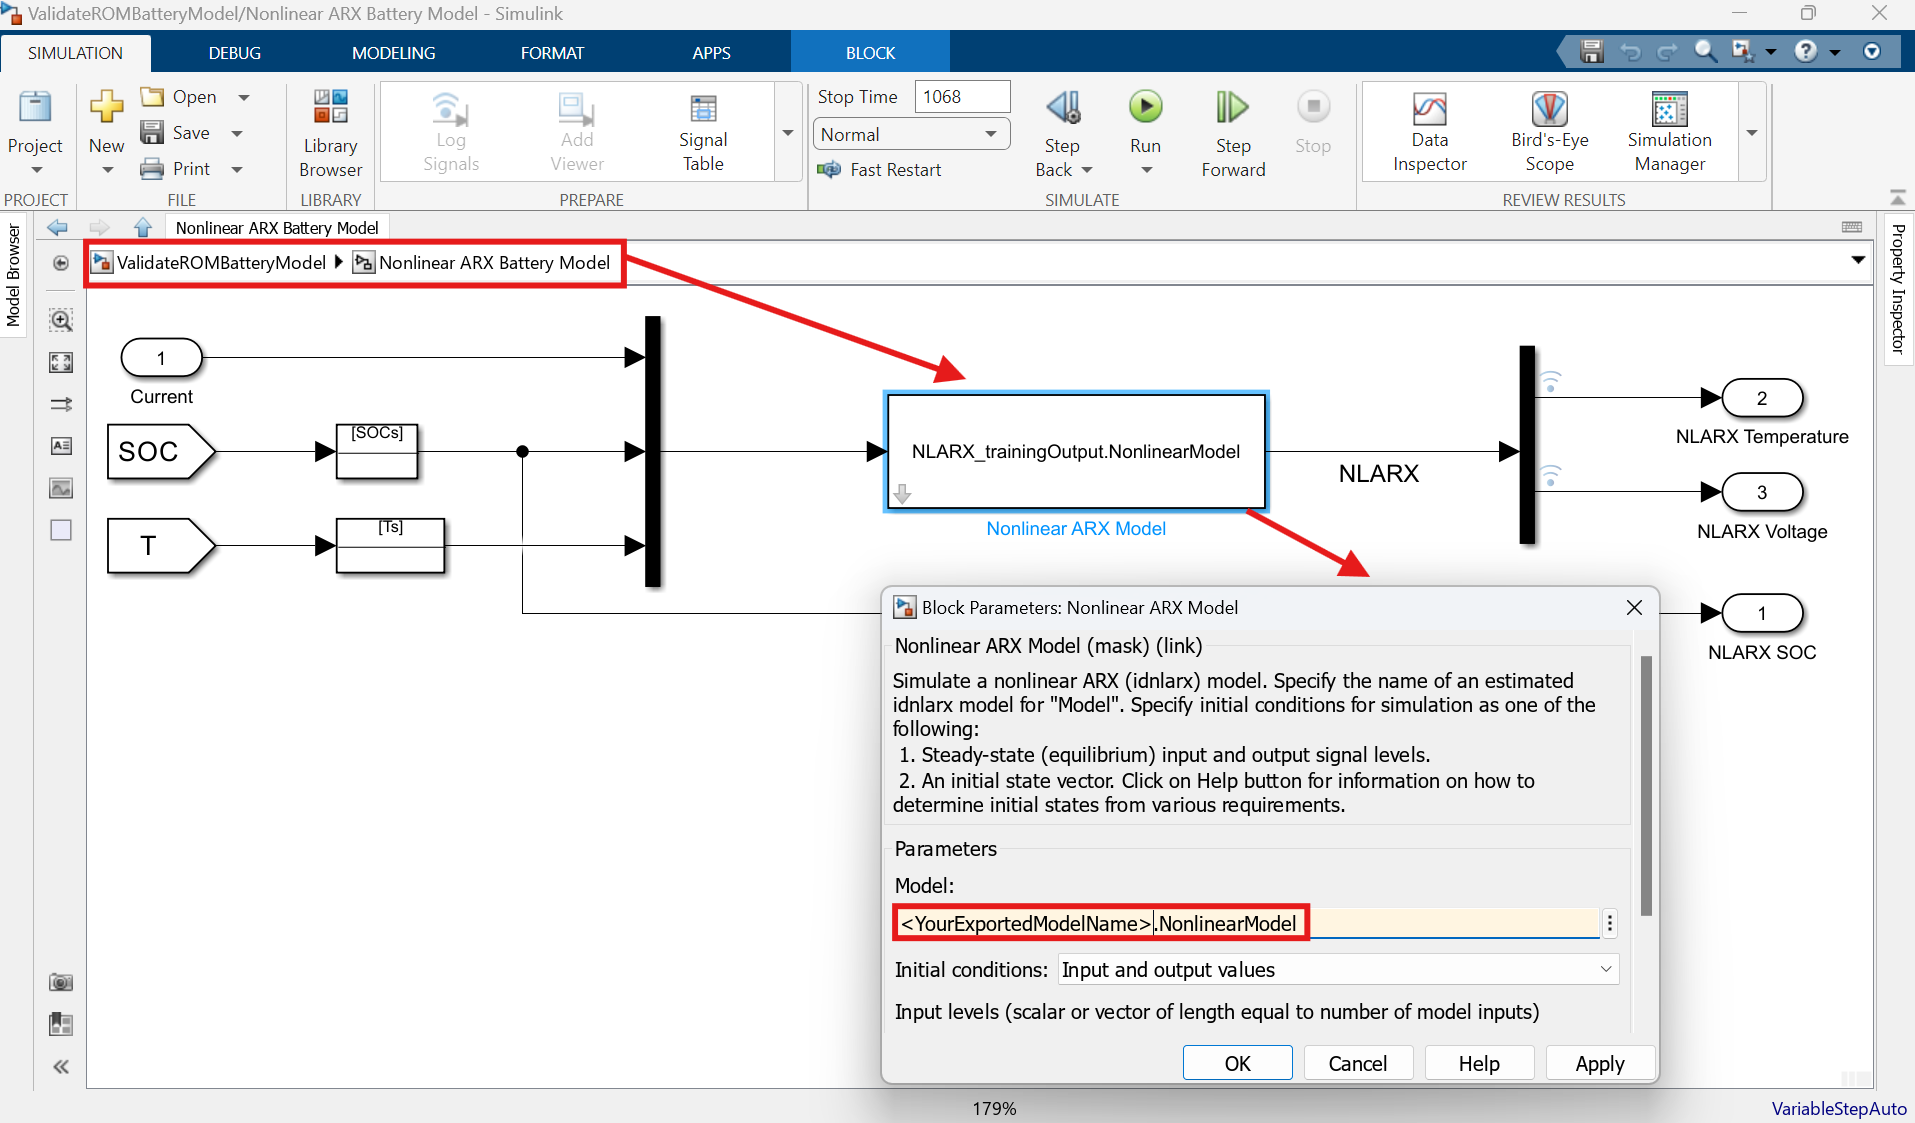

Run the model to compare the results

sim("ValidateROMBatteryModel.slx");

Compare the results of the simulation models

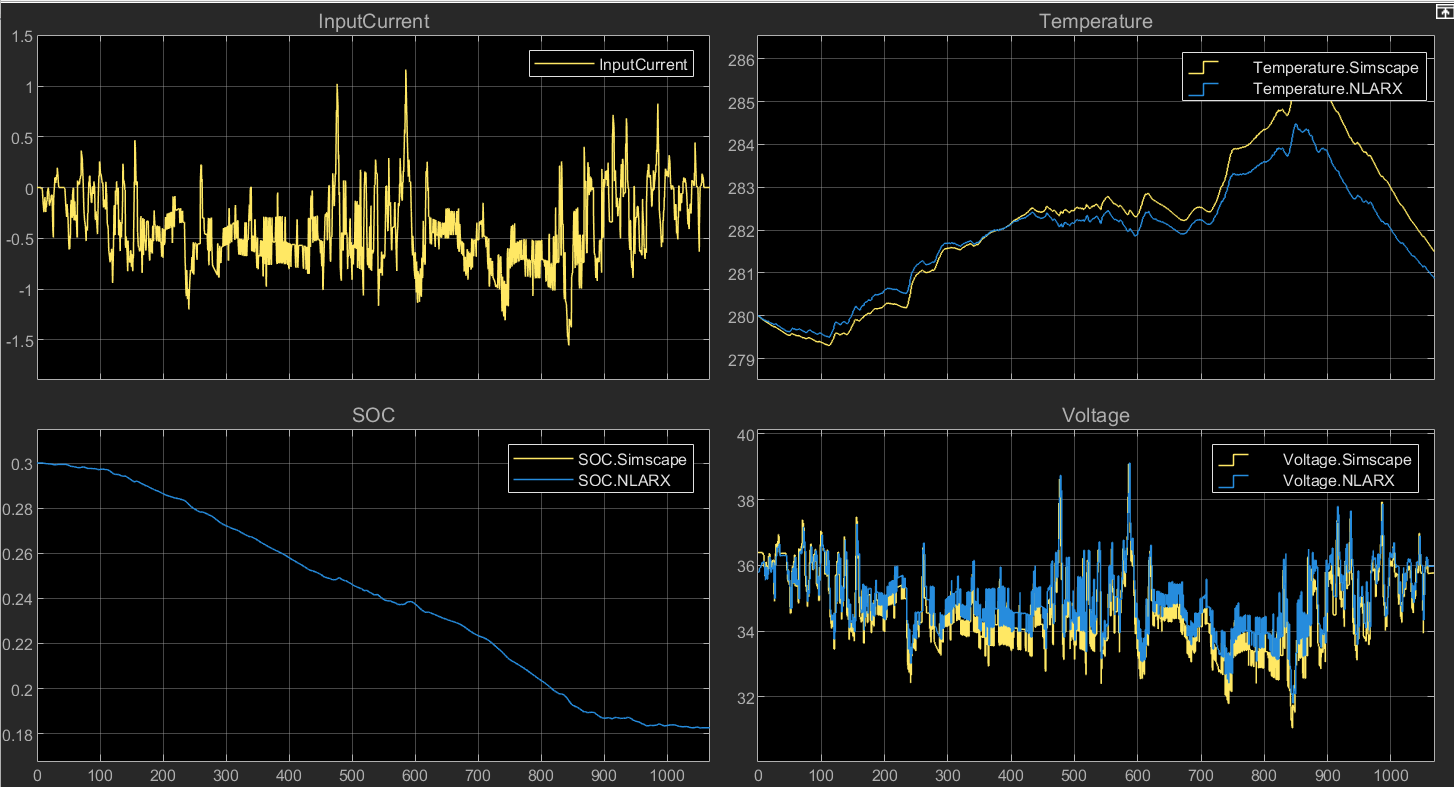

You can additionally vary initial SoC and initial temprature to validate results of ROM at different operating condtiions. 

SOCs = 0.5;
Ts = 290;
sim("ValidateROMBatteryModel.slx");

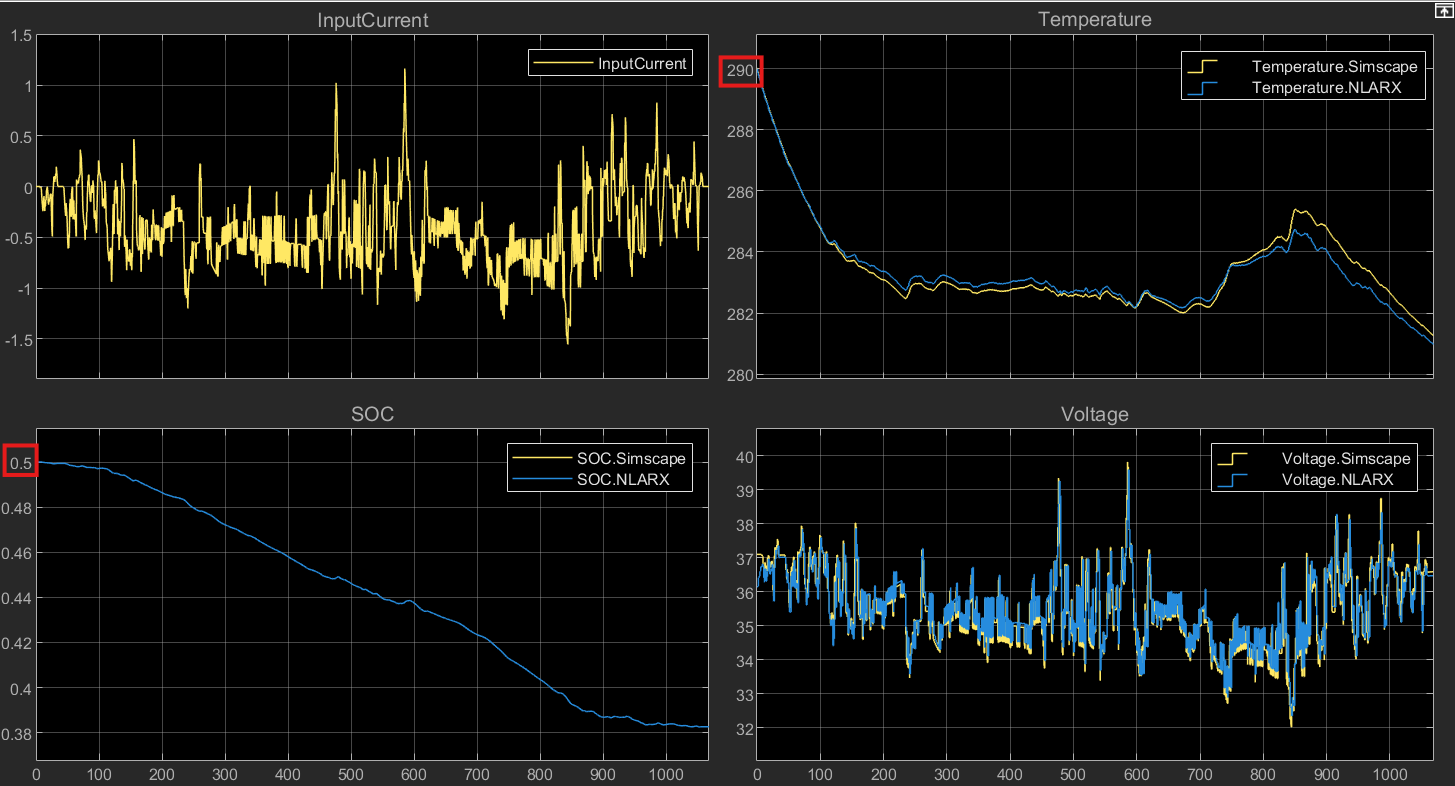

2. **Compare the model performance using Simulink profiler**

2.1 Open the Simulink Profiler dialog box using the Debug Tab

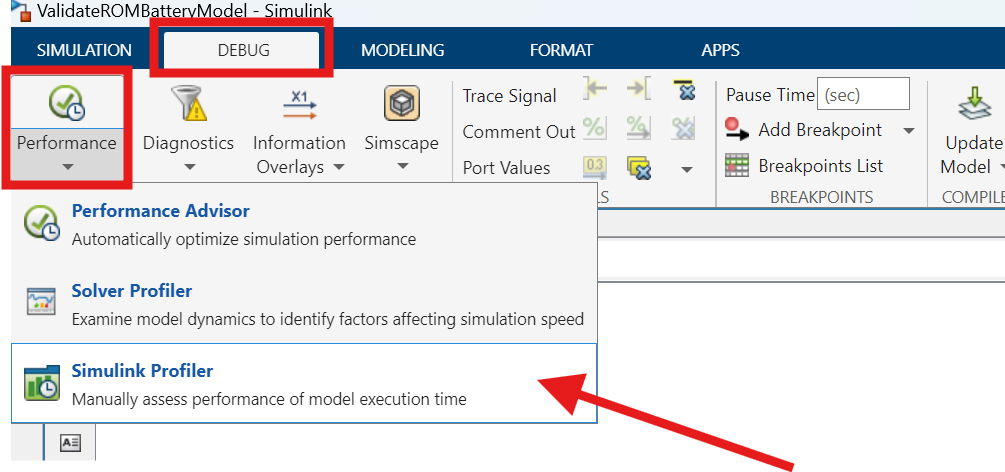

2.2 This will open up the Profiler Tab. Press the Profile button to run the profiler

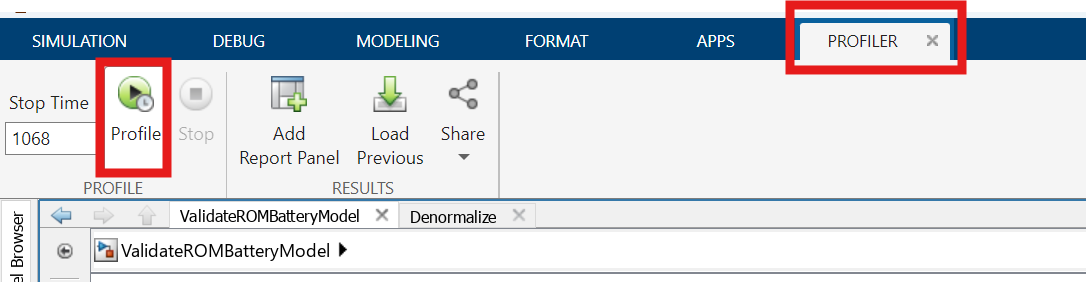

2.3 Analyze the profiler results to compare the ROM model. We can see that the inference time taken by the trained ROM model (Nonlinear ARX in this case) is ~4x faster than the original battery model. In this case we already had a fast running Simscape Battery model, you can expect more speed up for ROMs of high-fidelity 3rd-party battery models such as models based on COMSOL, PyBaMM, and GT-AutoLion. 

You can bring in these 3rd-party high-fidelity models as FMUs or S-functions and use the same workflow to create ROMs. 

Check [this page](https://www.mathworks.com/help/simulink/ug/understanding-total-time-and-self-time-in-profiler-reports.html) to understand the total time and self time in profler reports.

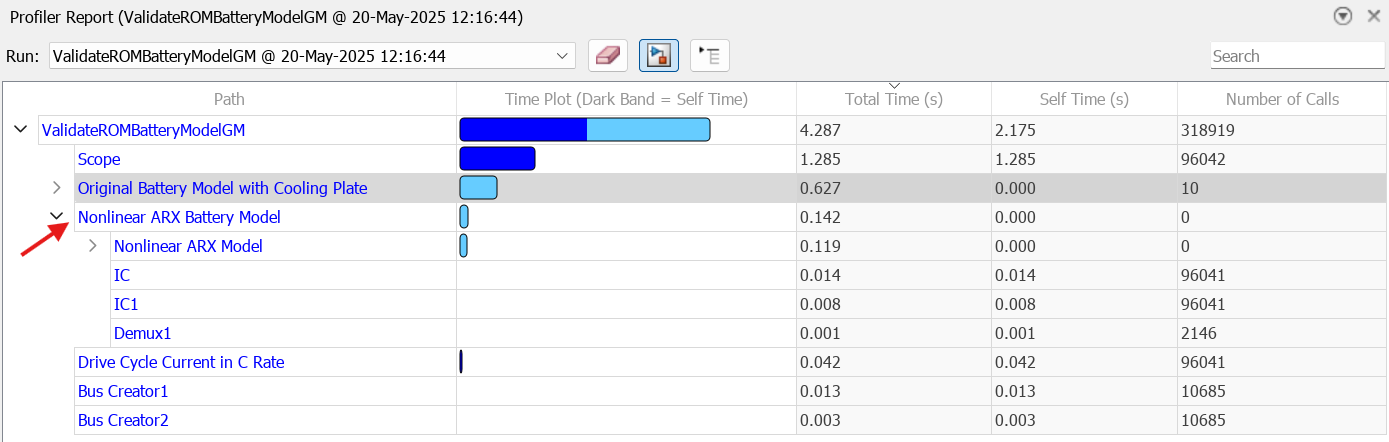

Clean up environment for next exercise

rmpath(ex1Folders);
clc
clear

*Copyright 2025, The MathWorks, Inc.*